# Квантовая механика и развитие информационных технологий

## Введение. Закон Мура и развитие информационных технологий

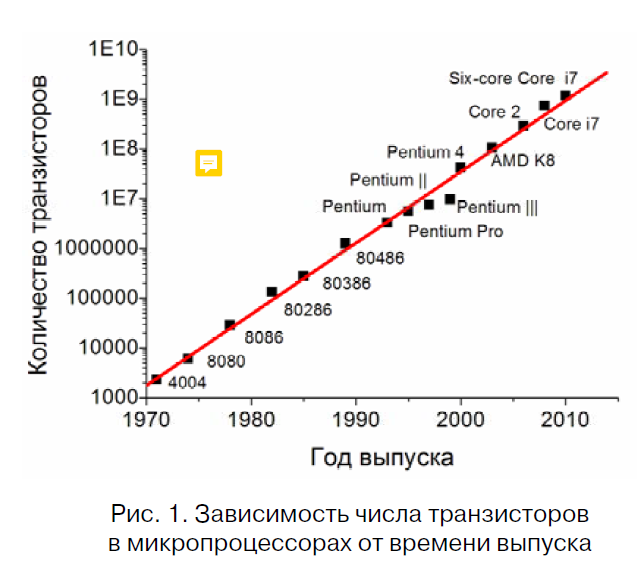

Интенсивное развитие микроэлектроники на протяжении последних более чем 50 лет вполне соответствует закону Мура. Для иллюстрации, на Рис. 1 представлена зависимость числа транзисторов в микропроцессорах за период с 1971 по 2011 годы. Представленная зависимость демонстрирует удвоение числа транзисторов каждые два года. Построено по данным компаний Intel (www.intel.com) и AMD (www.amd.com).

## 1. Алгоритм Шора и некоторые другие квантовые алгоритмы

Наилучший известный на сегодня классический алгоритм факторизации некоторого числа (так называемый метод решета числового поля - general number field sieve) требует для реализации следующее число операций:

clear
format short
digits(3)
syms n
L_class(n)=exp((sym(64/9))^(1/3)*n^(1/3)*(log(n))^(2/3))       % (1)

$$L\_class(n) = {\mathrm{e}}^{\frac{4\,9^{2/3}\,n^{1/3}\,{\log\left(n\right)}^{2/3}}{9}}$$

% где n = k⋅ln(10) - число двоичных знаков, а
% k- число соответствующих десятичных знаков,
% задающих это число.
syms k
n1(k)=vpa(k*log(10))

$$n1(k) = 2.3\,k$$

L1=vpa(L_class(n1(500)))

$$L1 = 1.51e+32$$

t1=L1/1e15    % время в с

$$t1 = 1.51e+17$$

t1=t1/(60*60*24*365)

$$t1 = 4.78e+9$$

% 5 млрд лет

L_quant(n)=n^2*log(n)*log(log(n))

$$L\_quant(n) = n^{2}\,\log\left(\log\left(n\right)\right)\,\log\left(n\right)$$

L2=vpa(L_quant(n1(500)))

$$L2 = 1.82e+7$$

t2=L2/1e6

$$t2 = 18.2$$

% 18 с

## 2. Кубит vs. бит (логический анализ)

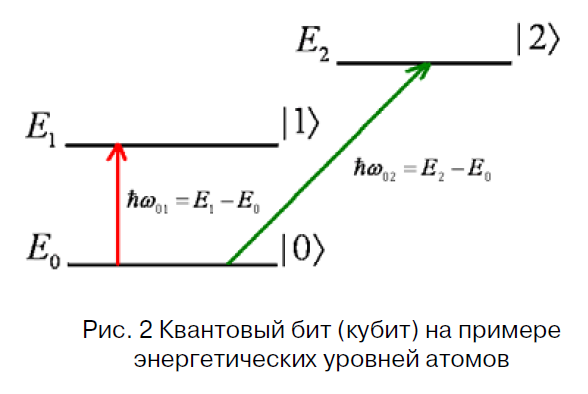

Так же как и классический бит, кубит может находиться в двух базисных состояниях  |0> и

|1> . Пусть в качестве кубита выступает, например, атом. Пусть, как показано на Рис. 2,  |0> - это основное состояние, а |1> - некоторое возбужденное долгоживущее состояние. Именно эти состояния и образуют кубит.

Фундаментальное правило, открытое Борном и фон Нейманом и определяющее статистический аспект квантовой теории, гласит, что вероятность обнаружить систему в состоянии |ϕ> при условии, что она была приготовлена в состоянии |ψ> , задается квадратом модуля их скалярного произведения:

$F=|<\varphi |\psi {>|}^2$                 (3)

Введенная величина F называется степенью согласованности или вероятностью совпадения квантовых состояний (fidelity). 

Заметим, что наряду с чистыми состояниями существуют и так называемые смешанные состояния, описываемые в рамках формализма матрицы плотности и соответствующие некогерентным смесям чистых состояний. Смешанные состояния обладают энтропией, которую можно вычислить по формуле фон Неймана:

$S=-\sum_j \lambda_j {\mathrm{log}}_2 \lambda_j$                       (4)

## 3. Представление состояния кубита на сфере Блоха

Квантовое состояние кубита представляет собой суперпозицию двух базисных состояний

физической системы:

syms c0 c1
ket0=[1;0]

ket0 =      1
     0


ket1=[0;1]

ket1 =      0
     1


ketpsi=c0*ket0+c1*ket1                    % (5)

$$ketpsi = \left(\begin{array}{c} c_{0}\\ c_{1} \end{array}\right)$$

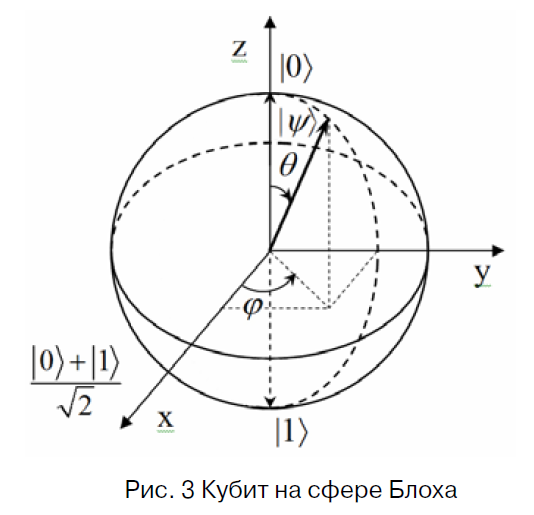

Оказывается, что все множество квантовых состояний кубита можно наглядно представить на так называемой сфере Блоха, очень похожей на глобус. Каждое чистое однокубитовое состояние задается точкой на сфере Блоха, положение которой определяется полярным θ и азимутальным ϕ углами (Рис. 3):

syms ket(psi) theta phi
ket(psi)=[cos(theta/2)*exp(-i*phi/2);sin(theta/2)*exp(i*phi/2)]    % (6)

$$ket(psi) = \left(\begin{array}{c} \cos\left(\frac{\theta }{2}\right)\,{\mathrm{e}}^{-\frac{\varphi \,\mathrm{i}}{2}}\\ \sin\left(\frac{\theta }{2}\right)\,{\mathrm{e}}^{\frac{\varphi \,\mathrm{i}}{2}} \end{array}\right)$$

Вычислительные операции задаются посредством унитарных вращений на сфере Блоха. Оператор унитарных вращений на угол θ относительно единичной оси n определяется следующей формулой:

syms theta sigma n I R_n(theta)
R_n(theta)==exp(-i*theta*sigma*n/2)==cos(theta/2)*I-sin(theta/2)*sigma*n    % (7)

$$ans = \left(R_{n}\left(\theta \right)={\mathrm{e}}^{-\frac{n\,\sigma \,\theta \,\mathrm{i}}{2}}\right)=\text{I}\,\cos\left(\frac{\theta }{2}\right)-n\,\sigma \,\sin\left(\frac{\theta }{2}\right)$$

% где sigma=(sigma1,sigma2,sigma3) - матрицы Паули, I - единичная матрица.

## 4. Квантовое измерение и квантовый скачок

## 5. Системы кубитов и квантовая запутанность

Двухкубитовое состояние представляет собой суперпозицию 4-х базисных состояний:

syms ket00 ket01 ket10 ket11 c00 c01 c10 c11
ketpsi=c00*ket00+c01*ket01+c10*ket10+c11*ket11              % (8)

$$ketpsi = c_{00}\,{\mathrm{ket}}_{00}+c_{01}\,{\mathrm{ket}}_{01}+c_{10}\,{\mathrm{ket}}_{10}+c_{11}\,{\mathrm{ket}}_{11}$$

% где
abs(c00)^2+abs(c01)^2+abs(c10)^2+abs(c11)^2==1

$$ans = {\left|c_{00}\right|}^{2}+{\left|c_{01}\right|}^{2}+{\left|c_{10}\right|}^{2}+{\left|c_{11}\right|}^{2}=1$$

Состояние системы, образованной двумя подсистемами, называется незапутанным, если оно может быть представлено в виде тензорного произведения векторов состояний отдельных кубитов:

$|\psi >=|\psi_1 >\otimes \;|\psi_2 >$                         (9)

В противном случае состояние называется запутанным. Для регистра из двух кубитов состояние (8) незапутанное, если выполняется условие:

c00*c11-c01*c10==0                  % (10)

$$ans = c_{00}\,c_{11}-c_{01}\,c_{10}=0$$

Так, состояние


$$|\psi >\;=\frac{1}{2}\left(\left|00>-\right|01>+\left|10>-\right|11>\right)$$


является незапутанным, поскольку может быть представлено в виде тензорного произведения


$$|\psi >\;=\frac{1}{\sqrt{2}}\left(\left|0>+\right|1>\right)\otimes \frac{1}{\sqrt{2}}\left(\left|0>-\right|1>\right)$$


Напротив, состояние


$$|\psi >\;=\frac{1}{\sqrt{2}}\left(\left|01>-\right|10>\right)$$


является запутанным, т.к. не может быть записано в виде прямого произведения состояний отдельных кубитов (представленное в этом примере состояние называется синглетным).

Действие оператора CNOT на базисные состояния двухкубитового регистра описывается следующей таблицей (таблица истинности):

CNOT:   $\begin{array}{l}
|00>\to |00>\\
|01>\to |01>\\
|10>\to |11>\\
|11>\to |10>
\end{array}$                                    (11)

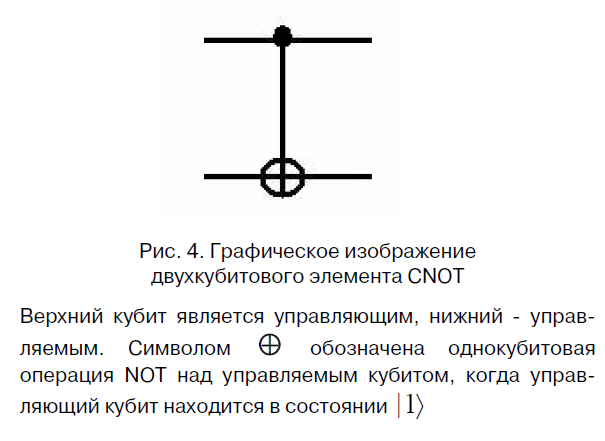

Графически вентиль CNOT представлен на Рис. 4

Унитарное преобразование CNOT задается следующей матрицей

$\mathrm{CNOT}=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 0 & 1\\
0 & 0 & 1 & 0
\end{array}\right\rbrack$               (12)

Преобразование CNOT может переводить незапутанные состояния в запутанные, например


$$\frac{1}{\sqrt{2}}\left(\left|0>-\right|1>\right)\otimes |1>\;=\frac{1}{\sqrt{2}}\left(\left|01>-\right|11>\right)$$


в синглет $\frac{1}{\sqrt{2}}\left(|01>-|10>\right)$

## 6. Общие требования, необходимые для реализации квантовых компьютеров

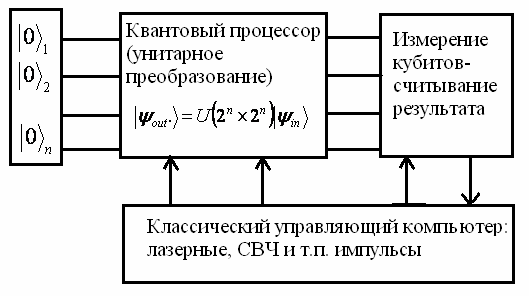

Рис. 5. Блок-схема идеального квантового компьютера